# Identificación de fricción y diseño PID para planta angular

Live script documentado por secciones. Ejecuta cada sección en orden, revisando las figuras y los mensajes que aparecen en consola antes de avanzar.

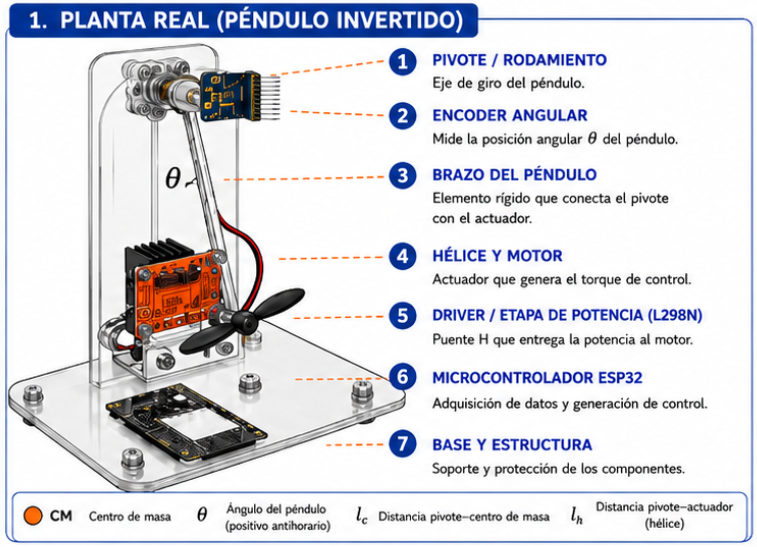

## IDENTIFICACIÓN DE FRICCIÓN Y DISEÑO PID PARA PLANTA ANGULAR

Objetivo del live script: identificar la fricción viscosa del sistema usando datos experimentales, validar el parámetro estimado con Simulink, obtener una planta linealizada y diseñar un controlador PID. La organización por secciones permite ejecutar el archivo paso a paso y verificar cada resultado antes de continuar.

%% IDENTIFICACIÓN DE FRICCIÓN Y DISEÑO PID PARA PLANTA ANGULAR
% Este script realiza el flujo completo usado en el trabajo:
% 1. Define los parámetros físicos del sistema.
% 2. Lee un experimento desde Excel.
% 3. Estima la fricción viscosa a partir de la envolvente de oscilación.
% 4. Valida el parámetro estimado con una simulación en Simulink.
% 5. Obtiene una planta linealizada alrededor de un punto de operación.
% 6. Diseña un PID por lugar de raíces.
% 7. Discretiza el controlador para una posible implementación digital.
% 8. Simula el lazo cerrado en Simulink.

clear; clc; close all;

## 1. PARÁMETROS FÍSICOS DEL SISTEMA

En esta sección se declaran las constantes físicas del montaje. Estos valores se usan durante todo el archivo, por eso conviene dejarlos al inicio. La inercia J se calcula como la suma de la inercia de la barra y la contribución aproximada del motor-hélice como masa puntual.

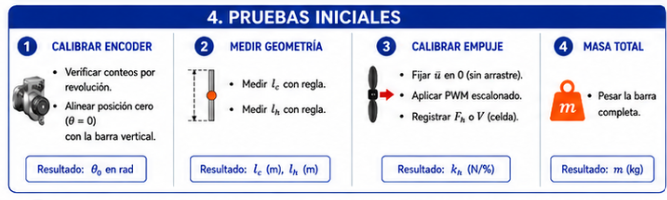

%% 1. PARÁMETROS FÍSICOS DEL SISTEMA
% Estos parámetros describen la barra, el conjunto motor-hélice y la gravedad.
% Con ellos se calcula la inercia total aproximada J.

g = 9.81;                         % Gravedad [m/s^2]
m_barra = 0.08;                   % Masa de la barra [kg]
L_barra = 0.195;                  % Longitud de la barra [m]
m_helice_motor = 0.002;           % Masa aproximada motor + hélice [kg]
L_cm_helice = 0.04;               % Distancia al centro de masa motor + hélice [m]

% Momento de inercia equivalente:
% - Barra: se aproxima como una barra girando alrededor de un extremo.
% - Motor/hélice: se aproxima como una masa puntual.
J = (1/3)*m_barra*L_barra^2 + m_helice_motor*L_cm_helice^2;

% Constante asociada al empuje/actuación. Ajusta este valor según tu calibración.
k = 2.06e-3 * 0.8;

## 2. CARGA Y PREPROCESAMIENTO DE DATOS EXPERIMENTALES

Aquí se importan los datos desde Excel y se limpian antes de usarlos. El archivo espera que cada experimento esté en una columna de la hoja indicada. También se reconstruye el tiempo suponiendo un muestreo constante de 10 ms.

%% 2. CARGA Y PREPROCESAMIENTO DE DATOS EXPERIMENTALES
% Se lee una columna de la hoja de Excel. Cada columna corresponde a un
% experimento. El tiempo se reconstruye suponiendo Ts = 10 ms.

archivo = 'Experimentos.xlsx';
hoja = 'Experimentos fricción';
expNum = 7;                       % Número del experimento a analizar
Ts = 0.01;                        % Periodo de muestreo [s]

data = readtable(archivo, ...
    'Sheet', hoja, ...
    'VariableNamingRule', 'preserve');

colAngulo = expNum + 1;           % La primera columna suele ser tiempo o índice
Angulo = data{:, colAngulo};

% Asegura que la señal sea numérica.
if ~isnumeric(Angulo)
    Angulo = str2double(string(Angulo));
else
    Angulo = double(Angulo);
end

% Elimina valores vacíos, NaN o infinitos.
Angulo = Angulo(isfinite(Angulo));

% Construye el vector de tiempo a partir del número de muestras.
N_muestras = numel(Angulo);
Tiempo = (0:N_muestras-1)' * Ts;

% Algunas bases de datos guardan 91.496° como 91496.
% Si la magnitud es demasiado grande para grados, se corrige la escala.
if median(abs(Angulo), 'omitnan') > 360
    Angulo = Angulo * 1e-3;
end

## 3. ESTIMACIÓN DE LA FRICCIÓN VISCOSA

La fricción se obtiene a partir del decaimiento de la oscilación libre. Primero se centra la señal respecto al equilibrio, luego se calcula una envolvente experimental y finalmente se ajusta una exponencial a los picos detectados.

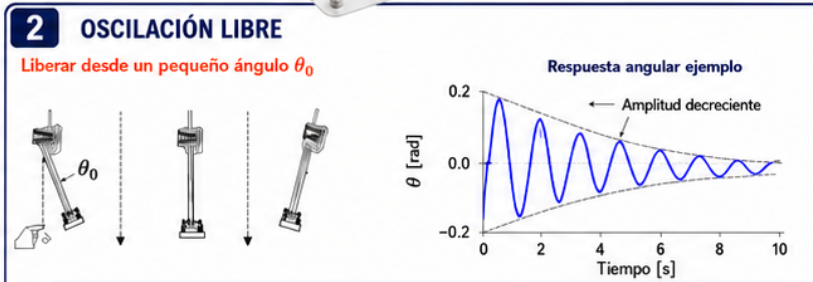

% La señal libre amortiguada se aproxima por una envolvente exponencial:
%
%     |theta(t) - theta_eq| = A exp(-sigma t)
%
% Para un sistema de segundo orden subamortiguado, la constante de
% decaimiento sigma permite estimar la fricción viscosa como:
%
%     b = 2 J sigma

% Estima el equilibrio con el promedio del último 15 % de los datos.
nFinal = max(10, round(0.15 * numel(Angulo)));
theta_eq = mean(Angulo(end-nFinal+1:end), 'omitnan');

AnguloCentrado = Angulo - theta_eq;

% Envolvente experimental aproximada.
env = abs(AnguloCentrado);
env = smoothdata(env, 'movmedian', 5);
env = smoothdata(env, 'movmean', 5);

% Detecta máximos de la envolvente. La distancia mínima evita tomar picos
% falsos causados por ruido.
minDist_s = 0.15;
[peaks, t_picos] = findpeaks(env, Tiempo, 'MinPeakDistance', minDist_s);

if isempty(peaks)
    error('No se detectaron picos. Revisa la señal o reduce minDist_s.');
end

% Descarta picos muy pequeños porque suelen estar dominados por ruido.
umbral = 0.05 * max(peaks);
idx_picos = peaks > umbral;
peaks = peaks(idx_picos);
t_picos = t_picos(idx_picos);

if numel(peaks) < 4
    error('Hay muy pocos picos para ajustar la exponencial.');
end

% Ajuste lineal de ln(peaks) = ln(A) - sigma*t.
coef = polyfit(t_picos, log(peaks), 1);
sigma_exp = -coef(1);
A_env = exp(coef(2));

% Fricción viscosa estimada para usar en el modelo.
b_p = 2 * J * sigma_exp;

fprintf('Envolvente experimental:\n');

Envolvente experimental:


fprintf('|theta - theta_eq| = %.4f exp(-%.4f t)\n', A_env, sigma_exp);

|theta - theta_eq| = 119.3907 exp(-0.9906 t)


fprintf('\nParámetro de fricción estimado:\n');


Parámetro de fricción estimado:


fprintf('J     = %.6e kg*m^2\n', J);

J     = 1.017200e-03 kg*m^2


fprintf('sigma = %.6f 1/s\n', sigma_exp);

sigma = 0.990584 1/s


fprintf('b_p   = %.6e N*m*s/rad\n', b_p);

b_p   = 2.015244e-03 N*m*s/rad


## 4. VALIDACIÓN DE LA FRICCIÓN EN SIMULINK

Con el valor estimado de fricción se ejecuta el modelo de Simulink y se compara la respuesta simulada contra los datos experimentales. Esta gráfica permite revisar si el parámetro b_p representa adecuadamente la disipación del sistema real.

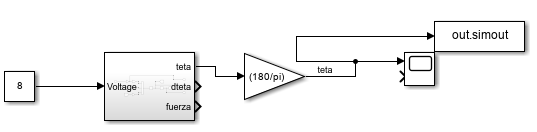

#### Sistema no lineal

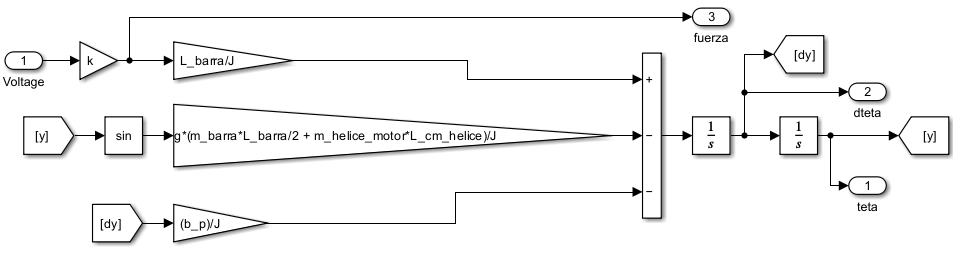

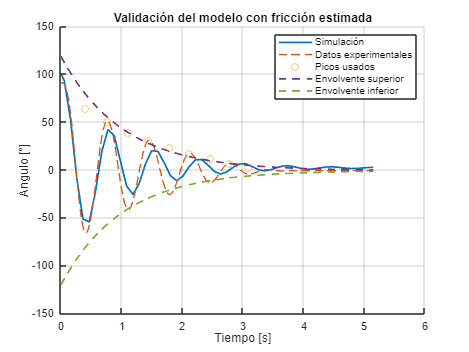

% El modelo de Simulink debe tener un bloque To Workspace llamado simout.
% Como este archivo es un script, las variables J, b_p, k, g, etc. quedan
% disponibles para Simulink en el workspace.

modelo_identificacion = 'modelo_protyecot';

out_id = sim(modelo_identificacion, 'StopTime', num2str(max(Tiempo)));
[TiempoSim_id, AnguloSim_id] = leerSalidaSimulink(out_id.simout);

% Curva ajustada de la envolvente.
t_fit = linspace(min(Tiempo), max(Tiempo), 300);
env_fit = A_env * exp(-sigma_exp * t_fit);

figure;
hold on; grid on;
plot(TiempoSim_id, AnguloSim_id, 'LineWidth', 1.5, ...
    'DisplayName', 'Simulación');
plot(Tiempo, Angulo, '--', 'LineWidth', 1.2, ...
    'DisplayName', 'Datos experimentales');
plot(t_picos, theta_eq + peaks, 'o', ...
    'DisplayName', 'Picos usados');
plot(t_fit, theta_eq + env_fit, '--', 'LineWidth', 1.5, ...
    'DisplayName', 'Envolvente superior');
plot(t_fit, theta_eq - env_fit, '--', 'LineWidth', 1.5, ...
    'DisplayName', 'Envolvente inferior');
xlabel('Tiempo [s]');
ylabel('Ángulo [°]');
title('Validación del modelo con fricción estimada');
legend('Location', 'northeast');

## 5. PLANTA LINEALIZADA PARA DISEÑO DEL CONTROLADOR

Para diseñar el PID se usa una aproximación lineal alrededor de un punto de operación. La planta resultante se expresa como función de transferencia con salida en grados, lo que facilita comparar la simulación con las mediciones.

%% 5. PLANTA LINEALIZADA PARA DISEÑO DEL CONTROLADOR
% Se linealiza el modelo alrededor de un punto de operación theta_op_deg.
% La salida se expresa en grados para que sea consistente con las mediciones.

s = tf('s');
theta_op_deg = 70;                % Punto de operación [°]

% Término gravitacional equivalente.
Mgl_equiv = g * (m_barra*L_barra/2 + m_helice_motor*L_cm_helice);

% Coeficientes del denominador de la planta linealizada.
a1 = b_p / J;
a2 = (Mgl_equiv / J) * cosd(theta_op_deg);

% Ganancia de entrada. Si k es fuerza por unidad de entrada, k*L_barra es torque.
num = k * L_barra / J;

% Planta con salida en grados.
G = minreal((180/pi) * num / (s^2 + a1*s + a2));

disp('Planta linealizada usada para diseño:');

Planta linealizada usada para diseño:


G


G =
 
          18.1
  ---------------------
  s^2 + 1.981 s + 25.99
 
Continuous-time transfer function.
Model Properties


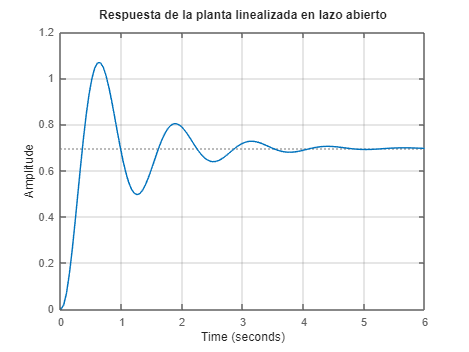


figure;
step(G);
grid on;
title('Respuesta de la planta linealizada en lazo abierto');

## 6. DISEÑO DEL PID POR LUGAR DE RAÍCES

El diseño se realiza de forma progresiva: primero se escoge Kp, luego Ki para eliminar error estacionario, y finalmente Kd para modificar la dinámica transitoria. El derivativo se implementa con filtro para evitar amplificar ruido.

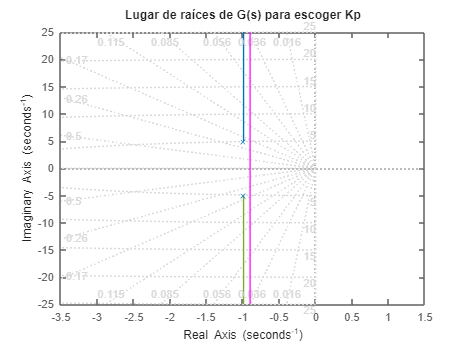

% Objetivo de diseño:
% - tiempo de establecimiento aproximado ts
% - sobrepico máximo aproximado Mp

ts = 5;                           % Tiempo de establecimiento deseado [s]
Mp = 0.05;                        % Sobrepico deseado, 0.05 = 5 %
zeta = -log(Mp) / sqrt(pi^2 + log(Mp)^2);
sigma_d = 4.5 / ts;               % Línea guía para rapidez de respuesta

% 6.1 Lugar de raíces de la planta para escoger Kp.
figure;
rlocus(G);
grid on;
sgrid(zeta, []);
xline(-sigma_d, 'm', 'LineWidth', 1.5);
title('Lugar de raíces de G(s) para escoger Kp');


Kp = 0.28;
T_P = feedback(Kp*G, 1);
info_P = stepinfo(T_P);

disp('Información del controlador P:');

Información del controlador P:


disp(info_P);

         RiseTime: 0.2143
    TransientTime: 3.6124
     SettlingTime: 3.6124
      SettlingMin: 0.1109
      SettlingMax: 0.2554
        Overshoot: 56.4998
       Undershoot: 0
             Peak: 0.2554
         PeakTime: 0.5579



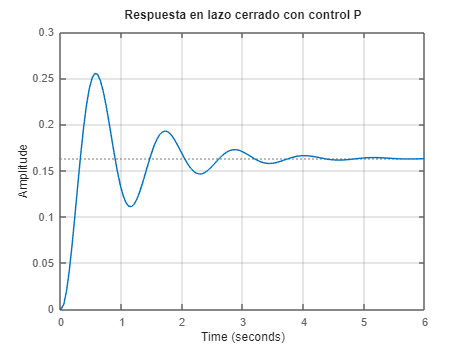


figure;
step(T_P);
grid on;
title('Respuesta en lazo cerrado con control P');

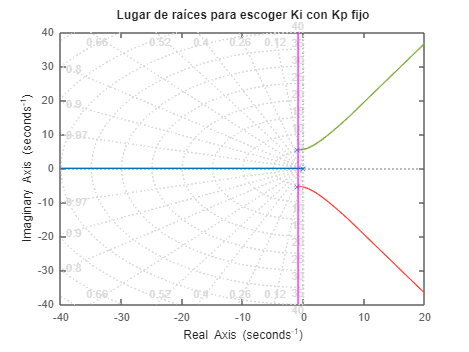


% 6.2 Lugar de raíces equivalente para escoger Ki con Kp fijo.
L_Ki = minreal(G / (s * (1 + Kp*G)));

figure;
rlocus(L_Ki);
grid on;
sgrid(zeta, []);
xline(-sigma_d, 'm', 'LineWidth', 1.5);
title('Lugar de raíces para escoger Ki con Kp fijo');


Ki = 1;
C_PI = Kp + Ki/s;
T_PI = feedback(C_PI*G, 1);
info_PI = stepinfo(T_PI);

disp('Controlador PI:');

Controlador PI:


C_PI


C_PI =
 
  0.28 s + 1
  ----------
      s
 
Continuous-time transfer function.
Model Properties


disp('Información del controlador PI:');

Información del controlador PI:


disp(info_PI);

         RiseTime: 3.5321
    TransientTime: 6.2052
     SettlingTime: 6.2052
      SettlingMin: 0.9051
      SettlingMax: 0.9987
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9987
         PeakTime: 10.7987



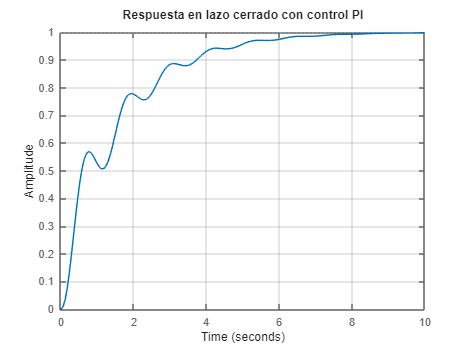


figure;
step(T_PI);
grid on;
title('Respuesta en lazo cerrado con control PI');

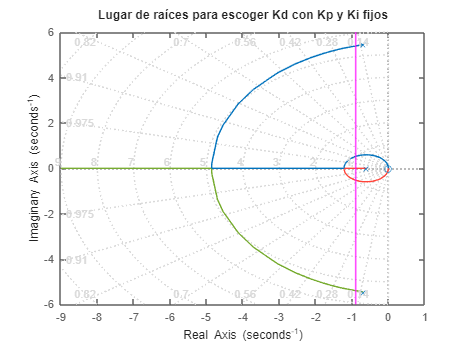


% 6.3 Lugar de raíces equivalente para escoger Kd con Kp y Ki fijos.
L_Kd = minreal((s*G) / (1 + G*(Kp + Ki/s)));

figure;
rlocus(L_Kd);
grid on;
sgrid(zeta, []);
xline(-sigma_d, 'm', 'LineWidth', 1.5);
title('Lugar de raíces para escoger Kd con Kp y Ki fijos');


Kd = 0.2;

% Filtro derivativo equivalente al bloque PID de Simulink.
N_filtro = 100;
Tf = 1 / N_filtro;
C_PID = Kp + Ki/s + Kd*(N_filtro*s)/(s + N_filtro);
T_PID = feedback(C_PID*G, 1);
info_PID = stepinfo(T_PID);

disp('Controlador PID con filtro derivativo:');

Controlador PID con filtro derivativo:


C_PID


C_PID =
 
  20.28 s^2 + 29 s + 100
  ----------------------
       s^2 + 100 s
 
Continuous-time transfer function.
Model Properties


disp('Información del controlador PID:');

Información del controlador PID:


disp(info_PID);

         RiseTime: 3.5100
    TransientTime: 6.0214
     SettlingTime: 6.0214
      SettlingMin: 0.9013
      SettlingMax: 0.9990
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9990
         PeakTime: 10.6716



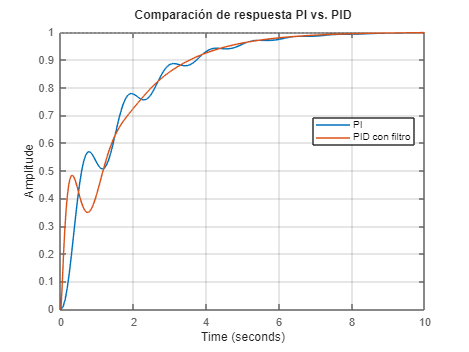


figure;
step(T_PI, T_PID);
grid on;
legend('PI', 'PID con filtro', 'Location', 'best');
title('Comparación de respuesta PI vs. PID');

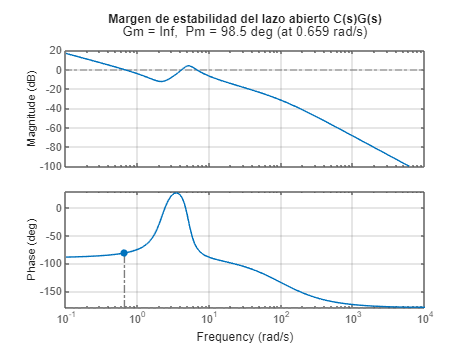


figure;
margin(C_PID*G);
grid on;
title('Margen de estabilidad del lazo abierto C(s)G(s)');

## 7. SIMULACIÓN DEL LAZO CERRADO EN SIMULINK

Con las ganancias seleccionadas se simula el modelo de lazo cerrado. Se usa un cambio pequeño de referencia para validar que la salida siga correctamente el punto de operación.

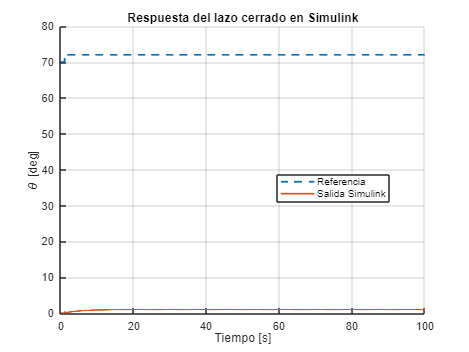

% El modelo lazo_cerrado debe usar las variables Kp, Ki, Kd, N_filtro, Tf,
% theta_ref_deg, theta_step_deg, theta_op_deg, t_step y u_op.

modelo_control = 'lazo_cerrado';
t_final = 100;

theta_ref_deg = theta_op_deg;         % Referencia inicial [°]
theta_step_deg = theta_op_deg + 2;    % Cambio pequeño de referencia [°]
t_step = 1;                           % Instante del cambio [s]
u_op = 0;                             % Entrada de operación, si aplica

% Si tu bloque PID de Simulink espera una variable llamada N, se iguala aquí.
N = N_filtro;

out_lc = sim(modelo_control, 'StopTime', num2str(t_final));
[TiempoSim_lc, AnguloSim_lc] = leerSalidaSimulink(out_lc.simout);

% Referencia para graficar.
theta_ref_plot = theta_ref_deg * ones(size(TiempoSim_lc));
theta_ref_plot(TiempoSim_lc >= t_step) = theta_step_deg;

figure;
hold on; grid on;
plot(TiempoSim_lc, theta_ref_plot, '--', 'LineWidth', 1.5, ...
    'DisplayName', 'Referencia');
plot(TiempoSim_lc, AnguloSim_lc, 'LineWidth', 1.5, ...
    'DisplayName', 'Salida Simulink');
xlabel('Tiempo [s]');
ylabel('\theta [deg]');
title('Respuesta del lazo cerrado en Simulink');
legend('Location', 'best');

## FUNCIONES AUXILIARES

Las funciones auxiliares se dejan al final porque MATLAB permite funciones locales al final de un script. En este caso, la función leerSalidaSimulink evita repetir código para interpretar la salida simout.


function [Tiempo, Salida] = leerSalidaSimulink(simout)
    if isa(simout, 'timeseries')
        Tiempo = simout.Time;
        Salida = simout.Data;
    elseif isstruct(simout) && isfield(simout, 'time')
        Tiempo = simout.time;
        Salida = simout.signals.values;
    elseif isnumeric(simout) && size(simout, 2) >= 2
        Tiempo = simout(:, 1);
        Salida = simout(:, 2);
    else
        error('No se reconoce el formato de out.simout.');
    end

    Tiempo = Tiempo(:);
    Salida = Salida(:);
end

## Notas de uso

Antes de ejecutar el live script, verifica que el archivo Experimentos.xlsx esté en la misma carpeta o en el path de MATLAB. También revisa que los modelos de Simulink se llamen modelo_protyecot y lazo_cerrado, y que ambos exporten una variable simout mediante un bloque To Workspace.